# calculating the fraction volume of a shell intersecting a cube

This impetus for this discussiocame from a calculation of the 2-point correlation function for discrete points in a 3D simulation cube (IllustrisTNG). 

The calculation involves finding the number density of objects at a given distance from a point at the center (periodic boundary conditions) - basically a spherical shell. This becomes problematic when the shell radius exceeds half the cube side since only part of the shell volume is enclosed in the cube and you will be missing objects. Stopping at the maximal distance (half a cube side) means ignoring 48% of the volume! 

To solve this we find a way to estimate the fraction volume of a shell intersecting a cube. We assume a unit sphere embedded in a cube of dimensions [-1 1] in each cartesian direction. The area of interest is 1<R<sqrt(3)

We wish to find the fractional volume of the red paerts within the blue lines. 

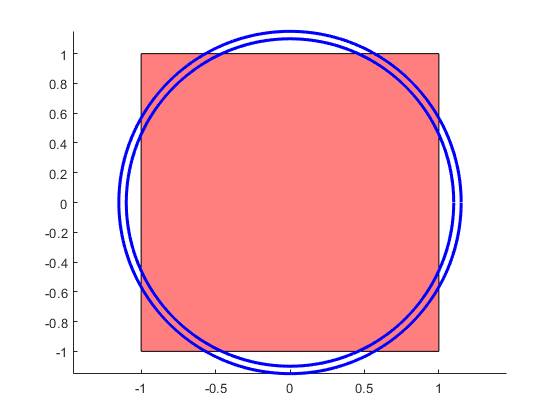

tt=0:0.01:2*pi;
figure
patch([-1 1 1 -1 -1],[-1 -1 1 1 -1],'r','facealpha',0.5)
hold on
plot(1.15.*cos(tt),1.15.*sin(tt),'b','linewidth',2)
plot(1.1.*cos(tt),1.1.*sin(tt),'b','linewidth',2)
axis equal

## The Method

Calculating directly is difficult - we used a point sampling method: we generate a set of points on a unit-sphere which represent the centers of an equal area polygon covering of the sphere. 

Below are examples for a smapling of 10x10 points: 

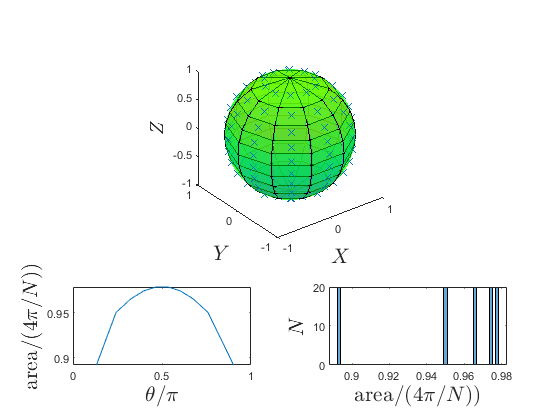

smplePnt=generateUnitSphereSampling(10,'show');

and  are examples for a smapling of 100x100 points: 

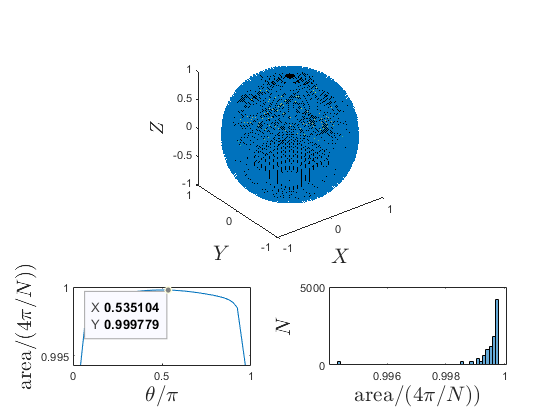

smplePnt=generateUnitSphereSampling(100,'show');

Note that the regions for which the polygon area is slightly lower are at the poles - which are less relevant for us. 

We then reproduce the smapling at a set of radii between R=-1 and R=sqrt(3), effectively filling the all the volume of a spherical shell between these two radii. To find the fractional intersectional volome of a shell we simply coune how many points are found within a given shello of R and dR and of those, what is the fraction that is also contined in the cube (intersection). 

The following function returns 3 arrays that enable this: a set of radii of samplings (rProf), the total number of points at a given radii and above (totalVolume), and the number of points at a given radii and above found in the intersectional volume with the cube (fracVolume).

vf=cube_in_shell_fracVol(100,100);


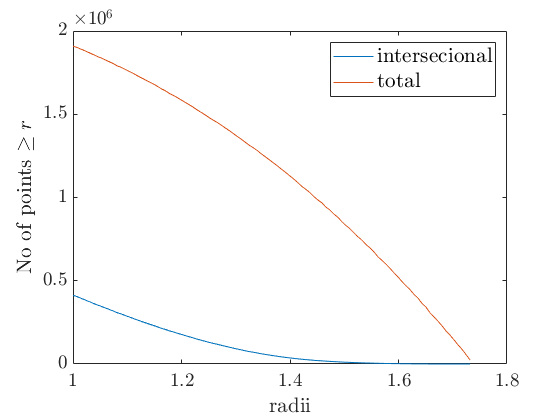


h=[];
figure
h(1)=plot(vf.rr,vf.fracVolume,'DisplayName','intersecional');
hold on
h(2)=plot(vf.rr,vf.totalVolume,'DisplayName','total');

legend(h,'Interpreter','latex','fontsize',16);
myAxis();
xlabelmine('radii');
ylabelmine('No of points $\ge r$');

To find the fractional volume of a shell intersecting a cube of radius   R and width dr you must find the relavent indices i1,i2 in the rProf  such that rProf(i1)=R and rProf(i2)-rProf(i1)=dr. The fractional voume is given by:

  v_frac=diff(intrsectVolume([i2 i1])./diff(totalVolume([i2 i1]).

Or by interpolation 

We show this for a shells of various radii and a set dr=0.01,0.05,0.1,0.15];

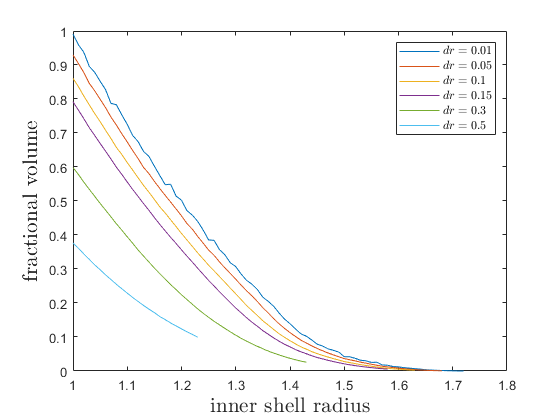

rShell=1:0.01:sqrt(3);
dr=[0.01 0.05 0.1 0.15 0.3 0.5];
for j=1:length(dr)
    
    fracVol=[];
    
    for i=1:length(rShell)
        
        if rShell(i)+dr(j)>sqrt(3)
            break;
        end
        
        n1=interp1(vf.rr,vf.fracVolume,rShell(i));
        n2=interp1(vf.rr,vf.fracVolume,rShell(i)+dr(j));
        n3=interp1(vf.rr,vf.totalVolume,rShell(i));
        n4=interp1(vf.rr,vf.totalVolume,rShell(i)+dr(j));
        
        fracVol(i)=(n1-n2)/(n3-n4);
    end
   
    plt(j).rShell=rShell(1:i-1);
    plt(j).fracVol=fracVol(1:i-1);
    
end

figure
h=[];
for j=1:length(dr)
    h(j)=plot(plt(j).rShell,plt(j).fracVol,'DisplayName',['$dr=' num2str(dr(j)) '$']);
    if j==1
        hold on
    end
end
legend(h,'interpreter',"latex",'fontsize',16);
myAxis()
    xlabelmine('inner shell radius');
    ylabelmine('fractional volume');

The fact that the line for dr=0.01 is wobbly shows that there is not enough resolution in the r direction. 

## Convergence

We now check the convergence of the result for the sampling density in the unit sphere and the r direction 

### smapling convergence on the unit sphere

We check this for a fiducia lvalue of dr=0.05

nn=[10 20 50 100 150 200];
rShell=1:0.01:sqrt(3);
dr=0.05;
for j=1:length(nn)
    fprintf('%i ',nn(j) )
    vf=cube_in_shell_fracVol(nn(j),100);
     fracVol=[];
    
    for i=1:length(rShell)
        
        if rShell(i)+dr>sqrt(3)
            break;
        end
        
        n1=interp1(vf.rr,vf.fracVolume,rShell(i));
        n2=interp1(vf.rr,vf.fracVolume,rShell(i)+dr);
        n3=interp1(vf.rr,vf.totalVolume,rShell(i));
        n4=interp1(vf.rr,vf.totalVolume,rShell(i)+dr);
        
        
        fracVol(i)=(n1-n2)/(n3-n4);
    end
   
    plt2(j).rShell=rShell(1:i-1);
    plt2(j).fracVol=fracVol(1:i-1);
    
end

10 20 50 100 150 200 

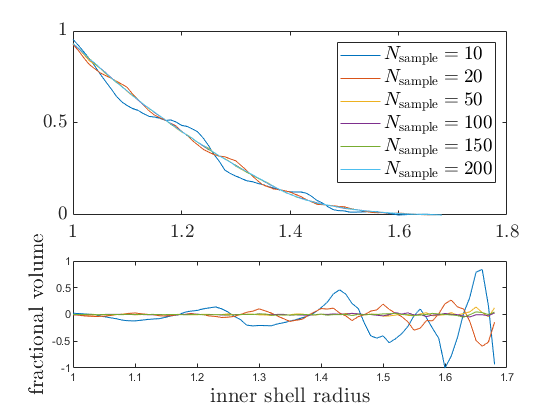


figure
tt=tiledlayout(5,1);
h=[];
nexttile([3,1])
for j=1:length(nn)
    h(j)=plot(plt2(j).rShell,plt2(j).fracVol,'DisplayName',['$N_\mathrm{sample}=' num2str(nn(j)) '$']);
    if j==1
        hold on
    end
end
legend(h,'interpreter',"latex",'fontsize',14);
myAxis();

nexttile([2 1])

for j=1:length(nn)-1
    plot(plt2(j).rShell,plt2(j).fracVol./plt2(end).fracVol-1);
    if j==1
        hold on
    end
end
    xlabelmine('inner shell radius');
    ylabelmine('fractional volume');

### sampling convergence in the r direction 

We take the same shell parameters as before and choose a unit sphere sampling of 100x100 

 
nr=[10 20 50 100 150 200 500 ];
rShell=1:0.01:sqrt(3);
dr=0.05;
for j=1:length(nr)
    fprintf('%i ',nr(j) )
    vf=cube_in_shell_fracVol(100,nr(j));
     fracVol=[];
    
    for i=1:length(rShell)
        
        if rShell(i)+dr>sqrt(3)
            break;
        end
        
        n1=interp1(vf.rr,vf.fracVolume,rShell(i));
        n2=interp1(vf.rr,vf.fracVolume,rShell(i)+dr);
        n3=interp1(vf.rr,vf.totalVolume,rShell(i));
        n4=interp1(vf.rr,vf.totalVolume,rShell(i)+dr);
        
        
        fracVol(i)=(n1-n2)/(n3-n4);
    end
   
    plt2(j).rShell=rShell(1:i-1);
    plt2(j).fracVol=fracVol(1:i-1);
    
end

10 20 50 100 150 200 500 

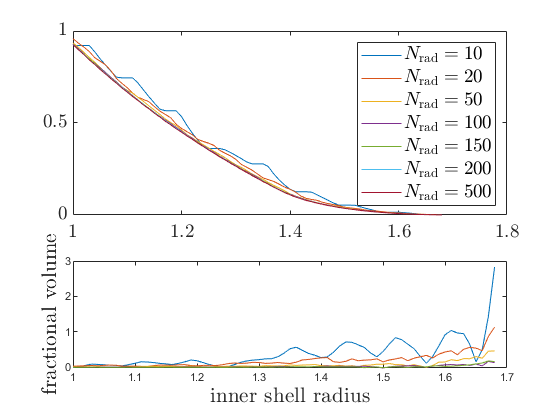


figure
tt=tiledlayout(5,1);
h=[];
nexttile([3,1])
for j=1:length(nr)
    h(j)=plot(plt2(j).rShell,plt2(j).fracVol,'DisplayName',['$N_\mathrm{rad}=' num2str(nr(j)) '$']);
    if j==1
        hold on
    end
end
legend(h,'interpreter',"latex",'fontsize',14);
myAxis();

nexttile([2 1])

for j=1:length(nn)-1
    plot(plt2(j).rShell,plt2(j).fracVol./plt2(end).fracVol-1);
    if j==1
        hold on
    end
end
    xlabelmine('inner shell radius');
    ylabelmine('fractional volume');

## Comparing to a parallel method

As a sanity check we try to calculate the fractional volume in a similar, but different approach: sampling the cube volume and then counting the points in the intersecting volume. 

npoint=1e6;

